## * CALISTA MAIN SCRIPT *

Example 7.Reconstruction of developmental trajectories during zebrafish embryogenesis (`Example_7_FARRELL_scDrop_seq.m` script in the main folder of CALISTA)

Analysis of Drop-seq data of Farrell et al. ([Farrell, J. A. et al. Single-cell reconstruction of developmental trajectories during zebrafish embryogenesis. Science 360, eaar3131 (2018)](http://science.sciencemag.org/content/360/6392/eaar3131.long)).

We begin with changing the current directory in MATLAB to the CALISTA folder. Type '`cd`' in the command window then copy and paste the current path in '`curr_path`':

clc
clear all
close all

% Add path for CALISTA folder:
% mfilename=matlab.desktop.editor.getActiveFilename;
% curr_path=fileparts(which(mfilename));

% In windows
curr_path='C:\Users\npgao\polybox\AAA ETH project CALISTA\CALISTA-MATLAB 1.2 dropout\CALISTA-MATLAB 1.2.1';
% In MacOS
% curr_path='/Users/nan/polybox/AAA ETH project CALISTA/CALISTA-MATLAB 1.2 dropout/CALISTA-MATLAB 1.2.1';

cd(curr_path);
addpath(genpath(curr_path))
warning ('off','all');

## * 1-Data Import and Preprocessing *

Type '`help import_data`' in the command window for more information 

Run the following section and import Farrell dataset (available in the subfolder *EXAMPLES/FARRELL*).

%% *** 1-Data Import and Preprocessing ***
%
% Type 'help import_data' for more information 
%
% Specify pre-processing settings
INPUTS.data_type=5; % snRNA-seq data
INPUTS.format_data=7; % (RECOMMENDED FOR Droplet-based datasets) File .mat containing the following variables:
%                       'expMatrix': NxG Log-expression matrix with rows=cells and columns=genes;
%                       'cellID': cell array/character vector containing cell IDs (not required)
%                       'geneNAMES': cell array containing gene names (not required)
%                       'timeline': 1xN numerical vector containing the time information (not required)INPUTS.zeros_genes=0.9; % Remove genes with > 90% of zeros 
INPUTS.zeros_genes=0.9; % Remove genes with > 90% of zeros 
INPUTS.top_genes=100; % Retain only top 100 genes
INPUTS.cluster_time=1; % Run CALISTA clustering for each time point separately
INPUTS.plot=0; % Do not show additional plots
% 
% Specify single-cell clustering settings
INPUTS.optimize=1; % Find the optimal number of clusters
INPUTS.use_drop_prob_in_clustering=1; % Consider the dropout probability in CALISTA
%
% Specify lineage inference settings
INPUTS.transition_new=1; % CALISTA automatically detect transition edges(required for Droplet-based datasets)
%
% Specify transition genes settings
INPUTS.thr_transition_genes=50; % Set threshold for transition genes determination to 50%
INPUTS.plot_trans_genes=0; % Do not show additional plots
%
% Specify landscape plotting settings
INPUTS.ngrid=300; % Grid size for 2D interpolation
%
% Specify path analysis settings
INPUTS.moving_average_window=10; % Set the size of window (percent of cells in each path) used for the moving averaging
INPUTS.path_auto=1; %Automatically detect paths along the graph based on shortestpath



% Upload and pre-process data 
[DATA,INPUTS]= import_data(INPUTS);


CALISTA processes the data from each time point separately.

## * 2-SINGLE-CELL CLUSTERING *

Type '`help CALISTA_clustering_main`' in the command window for more information. 

We run a CALISTA clustering for each data point as follows. First, the number of clusters at the final time point is determined using the eigengap plot. According to the eigengap plot below, we set the number of clusters to **23**. Then CALISTA will automatically detect the optimal number of clusters for the remaining time points.

[Results, DATA, INPUTS]=CALISTA_clustering_main(DATA,INPUTS);

If desired, users can remove cells from specific clusters from further analysis. In this example, we do not want to remove any clusters. Hence, we enter 0 (no cluster removal) and then 1 to proceed with lineage inference:

%  Cluster removal (if desired)
cluster_cut=input('Press 1 if you want to remove cell cluster(s). Press 0 otherwise: ');

if cluster_cut==1
    
   which_cut=input('Enter cluster index for removal (e.g 1 or [5 3]): ');
   cells_2_cut2=find(ismember(Results.final_groups,which_cut)==1);
   cells_2_cut2=DATA.cut_sort.abs_indices(cells_2_cut2);
   csvwrite('Cells_2_remove',cells_2_cut2)   
   RESULTS.cluster_cut = 1;
   fprintf('Cell''s indices to remove are saved in "Cells_2_remove.csv". Please run MAIN script again \n')
   return
end

Proceed=input(' Press 1 if you want to perform additional analysis (e.g. lineage inference, cell ordering) , 0 otherwise: ');
if ~Proceed
    return
end

## * 3-RECONSTRUCTION OF LINEAGE PROGRESSION *

Type '`help CALISTA_transition_main`' in the command window for more information. 

During the lineage inference step for time series Drop-seq data, CALISTA automatically generates and displays a lineage graph, obtained by calculating the shortest path between each cluster at the final cluster progression time and the starting cluster. The inferred lineage is represented by a tree-based graph:

[Results]=CALISTA_transition_main(DATA,INPUTS,Results);
% % Save 3D video
% figure(100)
% % daspect([2,2,0.3]);
% OptionZ.FrameRate=20;OptionZ.Duration=20.5;OptionZ.Periodic=true;
% CaptureFigVid([-20,10;-110,10;-190,80;-290,10;-380,10], 'CALISTA_lineage_3Dvideo',OptionZ)


Here, we do not need to remove any spurious edges, and hence we enter 0 upon queried.

## * 4-DETERMINATION OF TRANSITION GENES *

Type '`help CALISTA_transition_genes_main`' in the command window for more information. 

After reconstructing the lineage progression, we identify the key transition genes for any two connected clusters in the graph, based on the gene-wise likelihood difference between having the cells separately as two clusters and together as a single cluster. Larger differences in the gene-wise likelihood point to more informative genes. The transition genes are selected as those whose gene-wise likelihood differences make up to more than a certain percentage of the cumulative sum of the likelihood differences of all genes – set by` INPUTS.thr_transition_genes`.

[Results]=CALISTA_transition_genes_main(DATA,INPUTS,Results);

## * 5-PSEUDOTEMPORAL ORDERING OF CELLS *

Type '`help CALISTA_ordering_main`' in the command window for more information. 

For pseudotemporal ordering of cells, CALISTA performs maximum likelihood optimization for each cell using a linear interpolation of the cell likelihoods between any two connected clusters. The pseudotimes of the cells are computed by linear interpolation of the cluster pseudotimes, and correspond to the maximum point of the likelihood optimization above. Cells are subsequently assigned to the edges in the lineage progression graph. The following screenshot gives the results of this cell-to-edge assignment.

[Results]=CALISTA_ordering_main_2(DATA,INPUTS,Results);
% [Results_transition_genes]=CALISTA_ordering_main_2_transition_genes(DATA,INPUTS,Results);

## * 7-PATH ANALYSIS *

Type '`help CALISTA_path_main`' in the command window for more information. 

To plot the expression of marker genes along each path, users can enter 1 upon queried and load the excel file containing the list of genes if interest. In this case the file is in EXAMPLES/FARRELL:

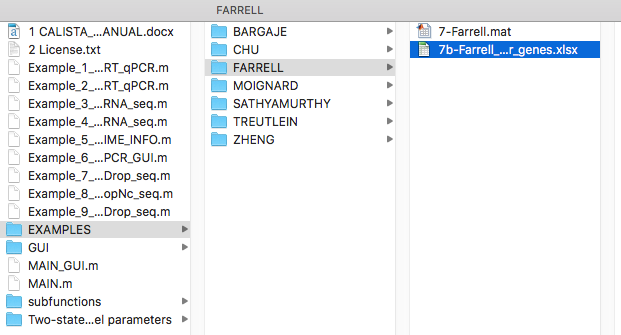

Proceed2=input(' Press 1 if you want to select transition paths and perform additional analysis, 0 otherwise: ');

if ~Proceed2
    return
end

[FileName,PathName,FilterIndex] = uigetfile('*.*');
filename=strcat(PathName, FileName);
selected_genes=importdata(filename);

Results=CALISTA_path_main(DATA,INPUTS,Results,'selected_genes',selected_genes);

% % check final cell types
% [FileName,PathName,FilterIndex] = uigetfile('*.*');
% filename=strcat(PathName, FileName);
% metadata=importdata(filename);
% metadata(DATA.cut_sort.idx2cutCELL,:)=[];
% metadata=metadata(DATA.cut_sort.idx_sorted_cells,:);
% 
% [FileName,PathName,FilterIndex] = uigetfile('*.*');
% filename=strcat(PathName, FileName);
% lineage=importdata(filename);
% 
% metadata2=metadata(find(DATA.timeline==max(DATA.timeline)),:);
% 
